clear

## 数据输入

% 母线（节点）信息
Nodes_old=["L2","L3","G1","L1","G2"]; %名称
NodeType_old=["PQ","PQ","PV","PQ","Slack"];%节点类型

Load=["L1","L2","L3"]; %负荷对应母线
LD_P=[-0.22,-0.18,-0.27]; %有功负荷
LD_Q=[-0.14,-0.09,-0.13]; %无功负荷

Gen=["G1","G2"]; %发电机对应母线
GE_P=[0.35,0];     %有功发电
GE_V=[1,1.05];   %母线电压幅值
GE_theta=[0];    %母线电压相角


AC_I=["L1","L2","L3","G1","G2"]; %I侧节点
AC_J=["L2","L3","G2","L3","L1"]; %J侧节点
AC_Z=[0.145+0.581j,0.104+0.518j,0.163+0.754j,0.031+0.248j,0.082+0.427j];%I-J阻抗
AC_y=[0.021j,0.018j,0.014j,0,0.028j];%I-J对地导纳参数

Trans_I=["G1"]; %k侧节点
Trans_J=["L3"]; %非k侧节点
Trans_k=[0.95]; %变比


## 潮流计算

%节点数据重排序 生成标准格式
[Nodes,P_s,Q_s,V0,theta0,n,n_pq,n_pv,n_bal]=DataProcess1(Nodes_old,NodeType_old,Load,LD_P,LD_Q,Gen,GE_P,GE_V,GE_theta);
%生成节点导纳矩阵
[G,B]=GenerateY(Nodes,AC_I,AC_J,AC_Z,AC_y,Trans_I,Trans_J,Trans_k);
Y=G+j*B;
eps=1e-5;
%迭代计算 并计时
tStart=tic;
[V,sita,V_vis,sita_vis]=powerFlowPQCalcu(n,n_pq,n_pv,n_bal,V0,theta0,G,B,P_s,Q_s,eps);

    1.0000         0         0         0
   -0.5399    1.0000         0         0
   -0.4714   -0.1444    1.0000         0
         0   -0.6897   -0.2081    1.0000

   -0.1800
   -0.3274
   -0.1983
    0.3225

    1.0000         0         0         0
   -0.5399    1.0000         0         0
   -0.4714   -0.1444    1.0000         0
         0   -0.6897   -0.2081    1.0000

   -0.1800
   -0.3274
   -0.2832
    0.3225

    1.0000         0         0         0
   -0.5399    1.0000         0         0
   -0.4714   -0.1444    1.0000         0
         0   -0.6897   -0.2081    1.0000

   -0.1800
   -0.3274
   -0.2832
    0.3225

    1.0000         0         0         0
   -0.5399    1.0000         0         0
   -0.4714   -0.1444    1.0000         0
         0   -0.6897   -0.2081    1.0000

   -0.1800
   -0.3274
   -0.3304
    0.3225

    1.0000         0         0         0
   -0.5399    1.0000         0         0
   -0.4714   -0.1444    1.0000         0
         0   -0.6897   -0.2081    1.0

tEnd=toc(tStart);


## 结果输出

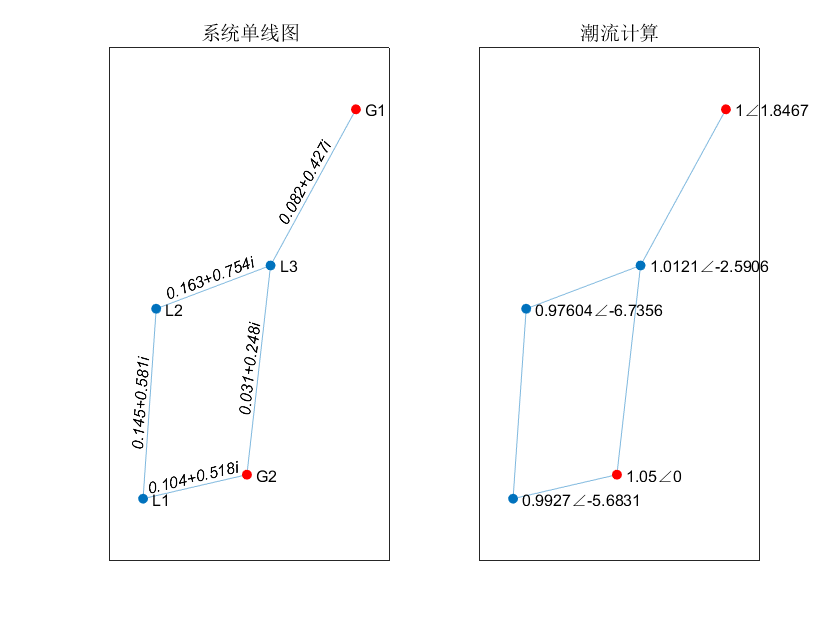


G=graph(AC_I,AC_J);

subplot(1,2,1)
H1=plot(G);%展示系统单线图
labeledge(H1,1:numedges(G),AC_Z);
highlight(H1,Gen,'NodeColor','r');
title("系统单线图")

subplot(1,2,2)
H2=plot(G);
highlight(H2,Gen,'NodeColor','r');
for i=1:length(Nodes)
    labelnode(H2,Nodes(i),strcat(num2str(V(i)),"∠",num2str(sita(i))))
end
title("潮流计算")



tEnd

tEnd = 0.0188

writematrix([Nodes;V;sita],"result.txt");